[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"biological disk in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Specimen properties

data = readmatrix('liver_properties.txt', 'CommentStyle','%');
f = data(:,1);
relative_permittivity = data(:,2);
conductivity          = data(:,3);

relative_permittivity_interpolant = griddedInterpolant(log(f),log(relative_permittivity));
conductivity_interpolant          = griddedInterpolant(log(f),log(conductivity));

relative_permittivity_func = @(f)exp(relative_permittivity_interpolant(log(f)));
conductivity_func          = @(f)exp(conductivity_interpolant(log(f)));

clear f relative_permittivity conductivity relative_permittivity_interpolant conductivity_interpolant

## Distributed Current Source

#### Coil

Coil.num = 3;
Coil.inner_radius = [3.75e-3 3.75e-3 3.75e-3]; % (m)
Coil.outer_radius = [6.00e-3 6.00e-3 6.00e-3]; % (m)
Coil.length       = [4.00e-3 3.00e-3 3.00e-3]; % (m)
Coil.z            = [6.00e-3 2.00e-3 10.0e-3]; % (m)

Coil.wire_diameter = [0.35e-3 0.08e-3 0.08e-3]; % (m)
Coil.N_turns = [60 1000 1000];
Coil.conductivity = 6e7 * ones(1,3); % (S/m)

#### Sensor

Sensor.num = 0;

#### Model

disk.radius = 30e-3; % (m)
disk.height = 10e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.01 seconds


clear disk r z

f = 50000;
Model.conductivity          = conductivity_func(f) * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = relative_permittivity_func(f) * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).
build governing equation took 19.97 seconds


#### Solve in frequency domain

Coil.frequency_domain.excitation = {"Current" 0.01; "Current" 0; "Current" 0}; % (A)

Coil.frequency_domain.frequency = f; % (Hz)
clear f

[Model, Coil, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 0.00 seconds


#### Plot world

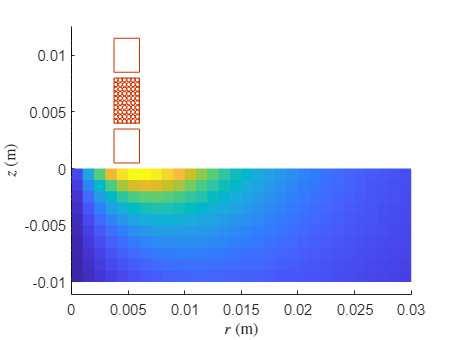

figure
PlotWorld2D(Model, Coil, Sensor, abs(Model.frequency_domain.J))

## Compare with FEA

#### Current density

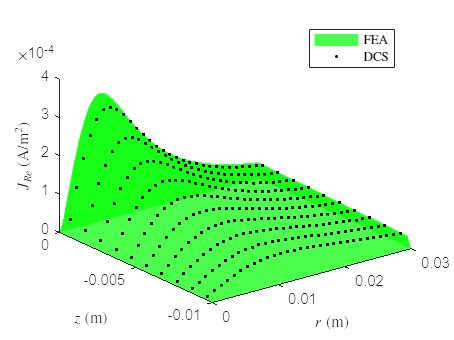

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.r = reshape(data(:,1), 100, []);
FEA.z = reshape(data(:,2), 100, []);
FEA.J = reshape(data(:,3), 100, []);
clear data

figure
hold on
surf(FEA.r,FEA.z, real(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elems_center(1,:), Model.elems_center(2,:), real(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.r', FEA.z', real(FEA.J)', Model.elems_center(1,:), Model.elems_center(2,:));
J_DSC = real(Model.frequency_domain.J);
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 0.022525%

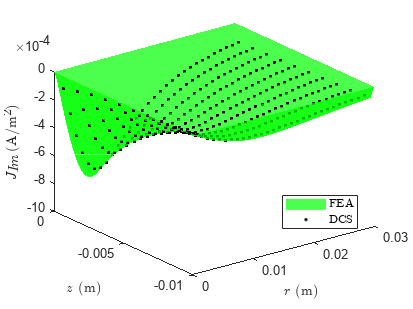


figure
hold on
surf(FEA.r,FEA.z, imag(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elems_center(1,:), Model.elems_center(2,:), imag(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.r', FEA.z', imag(FEA.J)', Model.elems_center(1,:), Model.elems_center(2,:));
J_DSC = imag(Model.frequency_domain.J);
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 0.012913%


clear J_FEA J_DSC error

#### Coil voltage

FEA_V = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
FEA_V = reshape(FEA_V(3:end), 3,2);
V_fix = (FEA_V(2,2) - FEA_V(3,2)) / 2;
FEA_V(2,:) = FEA_V(2,:) - V_fix;
FEA_V(3,1) = FEA_V(3,1) + V_fix;
FEA_V = FEA_V(:,1);

DCS_V = Coil.frequency_domain.V;

T = table([FEA_V(2);DCS_V(2)], [FEA_V(3);DCS_V(3)], [FEA_V(2)-FEA_V(3);DCS_V(2)-DCS_V(3)], 'VariableNames',["Lower coil voltage (V)","Upper coil voltage (V)","Differential voltage (V)"], 'RowNames',["FEA","DCS"]);
disp(T)

           Lower coil voltage (V)    Upper coil voltage (V)    Differential voltage (V)
           ______________________    ______________________    ________________________

    FEA     4.9941e-08+0.65647i       1.8531e-08+0.65647i        3.141e-08+1.2963e-08i 
    DCS     4.9731e-08+0.65698i       1.8496e-08+0.65698i       3.1235e-08+1.2889e-08i 



clear V_fix FEA_V DCS_V T

## Frequency Sweep

#### Plot specimen properties

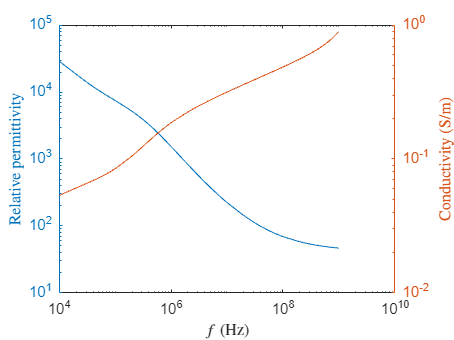

f = logspace(4, 9);

figure
yyaxis left
loglog(f, relative_permittivity_func(f))
ylabel("Relative permittivity", 'Interpreter','latex')
yyaxis right
loglog(f, conductivity_func(f))
ylabel("Conductivity (S/m)", 'Interpreter','latex')
xlabel("$f$ (Hz)", 'Interpreter','latex')

#### Coil differential voltage

V_diff = zeros(1, numel(f));
for i = 1:numel(f)
    Model.conductivity          = conductivity_func(f(i))          * ones(1,Model.num_elems); % (S/m)
    Model.relative_permittivity = relative_permittivity_func(f(i)) * ones(1,Model.num_elems); % (1)
    GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);

    [Model, Coil, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, Coil, Sensor);
    V_diff(i) = Coil.frequency_domain.V(2) - Coil.frequency_domain.V(3);
end

solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0

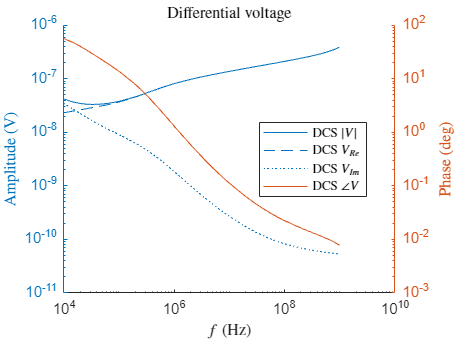


figure
hold on
yyaxis left
plot(f, abs (V_diff), 'DisplayName','DCS $|V|$')
plot(f, real(V_diff), 'DisplayName','DCS $V_{Re}$')
plot(f, imag(V_diff), 'DisplayName','DCS $V_{Im}$')
set(gca, 'YScale', 'log')
ylabel("Amplitude (V)", 'Interpreter','latex')

yyaxis right
plot(f, rad2deg(angle(V_diff)), 'DisplayName','DCS $\angle V$')
set(gca, 'YScale', 'log')
ylabel("Phase (deg)", 'Interpreter','latex')

set(gca, 'XScale', 'log')
xlabel("$f$ (Hz)", 'Interpreter','latex')
title("Differential voltage", 'Interpreter','latex')
legend('show', 'Location','best', 'Interpreter','latex')


clear f i V_diff